# FIR Based Zero‐Forcing (ZF) Linear Equalization

## 1 SYSTEM MODEL, GENERATION OF TRANSMITTED SYMBOLS AND MODELING THE ISI CHANNEL

### 1.1 SYSTEM MODEL

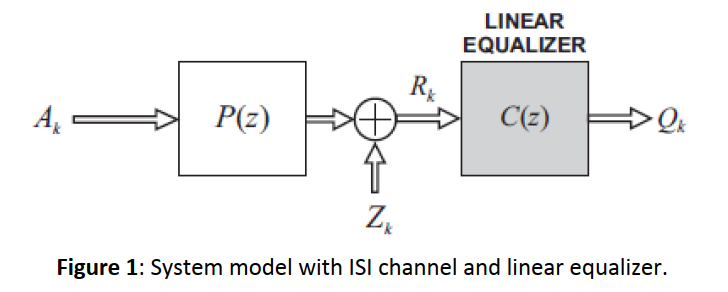

### 1.2 SYSTEM PARAMETERS AND TRANSMITTED SEQUENCE GENERATION

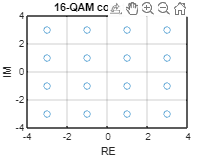

close all
clear all
clc
Rs = 20e6; %Let's define symbol rate for the plotting purposes

%% Creation of the data 
%16-QAM alphabet: 
a = repmat(-3:2:3,1,4)-[repmat(-3j,1,4) repmat(-1j,1,4) repmat(1j,1,4) repmat(3j,1,4)]; 
Ak = a(randi(16,1000,1)); % 16-QAM sequence of 1000 samples 

figure(1); plot(real(a),imag(a),'o'); title('16-QAM constellation'); grid; xlabel('RE'); 
ylabel('IM'); 

### 1.3 BASEBAND EQUIVALENT SYSTEM MODEL

%% Channel creation and channel modelling 
p = [0.19+.56j .45-1.28j -.14-.53j -.19+.23j .33+.51j]; % Example complex channel model
L1=1; L2=3; % Channel maximum tap is the second one, see p.317. we start with a pretty short 
% equalizer… later we increase the length also
figure(2); subplot(311); stem(-L1:L2,abs(p),'r');legend('ISI Channel');  
title('Absolute values of impulse responses'); % Absolute values of channel impulse response
%Plotting amplitude response of the channel: 
figure(4); [H,f]=freqz(p,1,-Rs/2:Rs/200:Rs/2,Rs); plot(f/1e6,20*log10(abs(H)),'b'); grid on; 
xlabel('Frequency [MHz]');ylabel('Amplitude response [dB]'); legend('ISI Channel'); 
title('Frequency Responses');

## 1.4 APPLYING THE ISI CHANNEL MODEL TO THE TRANSMITTED SEQUENCE

Rk = filter(p,1,Ak); % Received signal 
Rk = Rk(L1+1:end); % Discard the delay, if channel is anti-causal
figure(6);plot(real(Rk),imag(Rk),'o'); grid on; xlabel('RE');ylabel('IM'); % Constellation with ISI       

## 2 CHANNEL EQUALIZATION WITH LEAST SQUARES BASED AND INVERSION BASED ZF‐FIR EQUALIZERS

### 2.1 CHANNEL EQUALIZATION WITH LS BASED ZF‐FIR EQUALIZER

%% FIR zero forcing equalizer (LS approach on p.318) 
N1=2; N2=5; % Equalizer length is N1+N2+1 
P=convmtx(p.',N1+N2+1); % Convolution matrix (see lecture material p. 318) 
u_ZF=zeros(N1+N2+L1+L2+1,1); % u vector (zero forcing) (p.319) 
u_ZF(L1+N1+1)=1; % Puts the one in the place corresponding to channel delay. 
c_LS=((P'*P)\(P'))*u_ZF; % LS equalizer taps with pseudoinverse 
Rk_LS=filter(c_LS,1,Rk); % Equalized data 
Rk_LS=Rk_LS(L1+N1+1:end); % Discard the transient of the equalizer

## 2.2 CHANNEL EQUALIZATION WITH INVERSION BASED ZF‐FIR EQUALIZER

%% FIR zero forcing equalizer (alternative INV approach on p.320) 
P_alt=P(N1+L1+1-N1:N1+L1+1+N2,:); % Picking the correct row of P (p.320) 
u_alt=zeros(N1+N2+1,1); % u vector (zero forcing) (p.321) 
u_alt(N1+1)=1; % Puts the one in the center. 
c_INV=P_alt\u_alt; % INV equalizer taps with inverse 
Rk_INV=filter(c_INV,1,Rk); % Equalized data 
Rk_INV=Rk_INV(L1+N1+1:end); % Discard the transient of the equalizer

## 2.3 PLOTTING INTERESTING CURVES

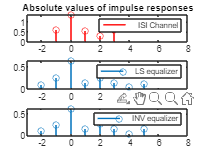

%% Plotting absolute values of the impulse responses of the equalizers 
figure(2);subplot(312);stem(-N1:N2,abs(c_LS)); legend('LS equalizer');  
axis([-N1-L1 N2+L2 0 Inf]); 
figure(2);subplot(313);stem(-N1:N2,abs(c_INV)); legend('INV equalizer');  
axis([-N1-L1 N2+L2 0 Inf]); 
figure(2); subplot(311); axis([-N1-L1 N2+L2 0 Inf]); 

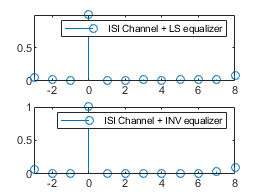

 

  

%% Plotting absolute values of the total impulse response of channel + LS/INV equalizers 
figure(3);subplot(211);stem(-N1-L1:N2+L2,abs(conv(p,c_LS)));  
legend('ISI Channel + LS equalizer'); axis([-N1-L1 N2+L2 0 Inf]); 
figure(3);subplot(212);stem(-N1-L1:N2+L2,abs(conv(p,c_INV)));  
legend('ISI Channel + INV equalizer'); axis([-N1-L1 N2+L2 0 Inf]); 

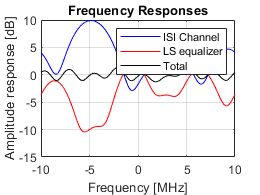


  
  

%% Plotting amplitude responses of the LS equalizer and the 
%% product of channel and LS equalizer 
figure(4); hold on; [H_LS,f]=freqz(c_LS,1,-Rs/2:Rs/200:Rs/2,Rs); 
plot(f/1e6,20*log10(abs(H_LS)),'r'); % Amplitude response of the LS equalizer 
figure(4); H_tot=H.*H_LS; plot(f/1e6,20*log10(abs(H_tot)),'k'); hold off; 
legend('ISI Channel','LS equalizer','Total') % Amplitude response of the channel+LS equalizer 

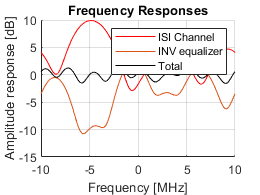


  

%% Plotting amplitude responses of the channel, INV equalizer 
%% and the product of channel and LS equalizer 
figure(5); hold on; plot(f/1e6,20*log10(abs(H)),'r'); grid on; title('Frequency Responses'); 
[H_INV,f]=freqz(c_INV,1,-Rs/2:Rs/200:Rs/2,Rs); % Amplitude response of the INV equalizer 
plot(f/1e6,20*log10(abs(H_INV))); 
xlabel('Frequency [MHz]');ylabel('Amplitude response [dB]'); 
H_tot_inv=H.*H_INV; plot(f/1e6,20*log10(abs(H_tot_inv)),'k'); hold off; 
legend('ISI Channel','INV equalizer','Total') % Amplitude response of the channel+INV equalizer 

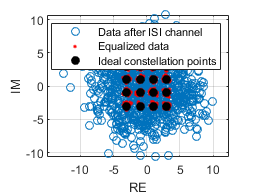


  

%% Plotting constellations (Comparing first method to non-equalized) 
figure(6); hold on; plot(real(Rk_LS),imag(Rk_LS),'r.'); % Equalized constellation 
plot(real(a),imag(a),'ko', 'MarkerSize',6,'MarkerFaceColor','k'); hold off; %Ideal constellation 
grid on; legend('Data after ISI channel','Equalized data','Ideal constellation points');  
axis equal;  

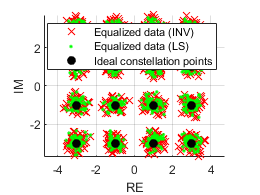

  
%% Plotting constellations (Comparing second method to first method) 
figure(7); hold on; 
plot(real(Rk_INV),imag(Rk_INV),'rx'); % LS equalized constellation 
plot(real(Rk_LS),imag(Rk_LS),'g.'); % INV equalized constellation 
plot(real(a),imag(a),'ko', 'MarkerSize',6,'MarkerFaceColor','k'); hold off; %Ideal constellation 
grid on; legend('Equalized data (INV)','Equalized data (LS)','Ideal constellation points'); 
xlabel('RE');ylabel('IM'); axis equal;